%run eerst
addpath('../Code/hulpFuncties/')

% data generation
[data_XA, data_YA, data_XB, data_YB] = random_data_generator(1000,100, "Cirkel");
%    matrix met datapunten
%     klasse A | klasse B
% 1      x_a   |   x_b   
% 2      y_a   |   y_b
% 3       1    |    0
% 4       0    |    1
data = [data_XA data_XB; data_YA data_YB; ones(1,length(data_XA)) zeros(1,length(data_XB)); zeros(1,length(data_XA)) ones(1,length(data_XB))]

data =     0.2780    0.6710    0.5750    0.1850    0.1720    0.2740    0.4320    0.8180    0.3730    0.2520    0.5990    0.3820    0.5770    0.7420    0.6300    0.5820    0.5450    0.7690    0.2510    0.2860    0.8520    0.8850    0.3600    0.5990    0.3400    0.5050    0.3760    0.5930    0.1430    0.6020    0.3630    0.2040    0.2770    0.7310    0.3400    0.4630    0.5090    0.5280    0.3950    0.3360    0.7540    0.3130    0.6340    0.5400    0.2970    0.1110    0.3130    0.4570    0.6590    0.2540
    0.3820    0.5780    0.3120    0.5240    0.4230    0.6440    0.5260    0.2710    0.1610    0.4150    0.1970    0.8370    0.5210    0.7690    0.7470    0.8650    0.2680    0.7290    0.6880    0.3510    0.6290    0.5140    0.3040    0.7970    0.7480    0.7140    0.3490    0.1880    0.3450    0.6900    0.4800    0.5180    0.5590    0.3400    0.7270    0.8090    0.8310    0.8140    0.6060    0.2610    0.4640    0.2730    0.1340    0.1450    0.1970    0.4980    0.2060    0.7670    0.2570  

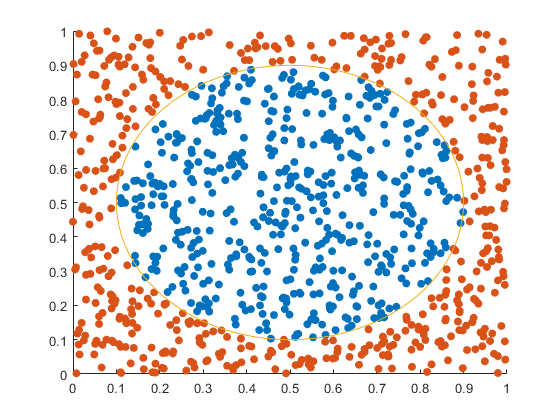


th = 0:pi/50:2*pi;
xunit = 0.4 * cos(th) + 0.5;
yunit = 0.4 * sin(th) + 0.5;

figure
hold on
axis([0 1 0 1])
scatter(data_XA,data_YA,'filled')
scatter(data_XB,data_YB,'filled')
plot(xunit, yunit);

%parameters
step = 0.25;
batch_size = 1;
max_iterations = 1e6;
model_params = [0, 10];

network = NN_gen([2 5 2],'normal',model_params,5000);
trained_network = train_net(network, data, step, max_iterations, batch_size, model_params, [0, 1]);

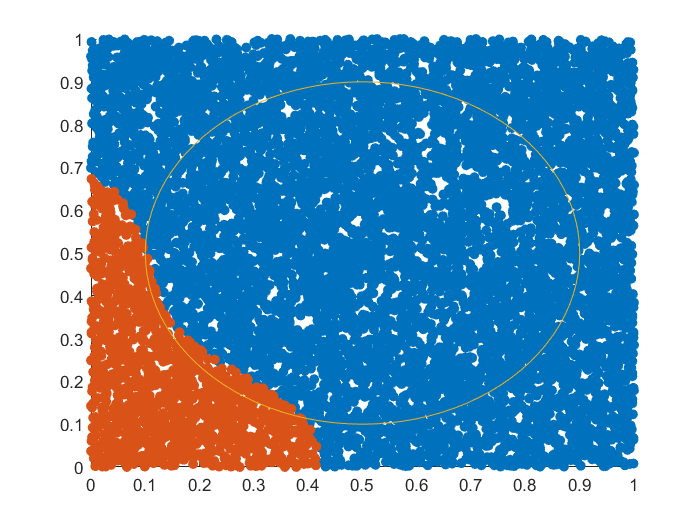

[data_XA, data_YA, data_XB, data_YB] = random_data_generator(10000,200,"Ster");

x1_t = [data_XA data_XB];
x2_t = [data_YA data_YB];
N = length(x1_t);

XA = {};
YA = {};
XB = {};
YB = {};

for c = 1:N
    x = [x1_t(c); x2_t(c)];
    % Forward pass
    a2 = sigmoid_activate(x,trained_network{1,1},trained_network{1,2});
    a3 = sigmoid_activate(a2,trained_network{1,3},trained_network{1,4});
    if a3(1) >= a3(2)
        XA = [XA, x1_t(c)];
        YA = [YA, x2_t(c)];
    else
        XB = [XB, x1_t(c)];
        YB = [YB, x2_t(c)];
    end
end

XA = cell2mat(XA);
YA = cell2mat(YA);
XB = cell2mat(XB);
YB = cell2mat(YB);

th = 0:pi/50:2*pi;
xunit = 0.4 * cos(th) + 0.5;
yunit = 0.4 * sin(th) + 0.5;

figure
hold on
axis([0 1 0 1])
%scatter(X,Y,[],'filled')
scatter(XA,YA,'filled')
scatter(XB,YB,'filled')
plot(xunit, yunit);

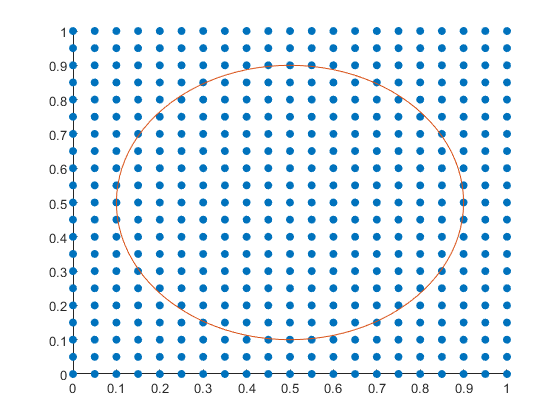

grid = gen_grid();
figure
hold on
axis([0 1 0 1])
scatter(grid(1,:), grid(2,:), 'filled')
plot(xunit, yunit);

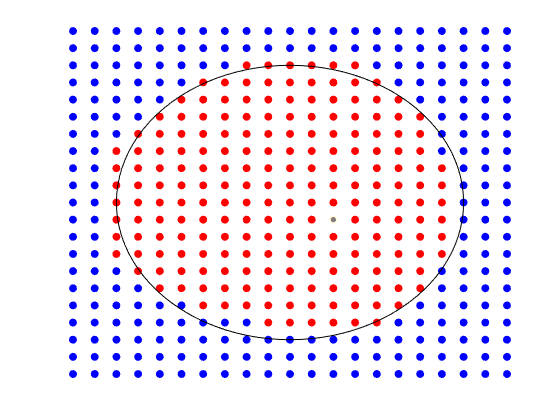

corClass = correct_classify_circle(grid);
XA = {};
YA = {};
XB = {};
YB = {};
cor_counter = 0;
for i = 1: length(grid)
    x = [grid(1,i); grid(2,i)];
    a = classify(x, trained_network);
    if a(1) >= a(2)
        XA = [XA, grid(1,i)];
        YA = [YA, grid(2,i)];
        if corClass{i} == "A"
            cor_counter = cor_counter + 1;
        end
    else
        XB = [XB, grid(1,i)];
        YB = [YB, grid(2,i)];
        if corClass{i} == "B"
            cor_counter = cor_counter + 1;
        end
    end
end

XA = cell2mat(XA);
YA = cell2mat(YA);
XB = cell2mat(XB);
YB = cell2mat(YB);

th = 0:pi/50:2*pi;
xunit = 0.4 * cos(th) + 0.5;
yunit = 0.4 * sin(th) + 0.5;

figure
hold on
axis([0 1 0 1])
%scatter(X,Y,[],'filled')
scatter(XA,YA,'red','filled')
scatter(XB,YB,'blue','filled')
plot(xunit, yunit,'black');

color = 'none';
set(gca,'XColor',color,'YColor',color,'TickDir','out')



(cor_counter/length(grid)) * 100

ans = 95.0113

%scatter(grid(1,:),grid(2,:),'filled')

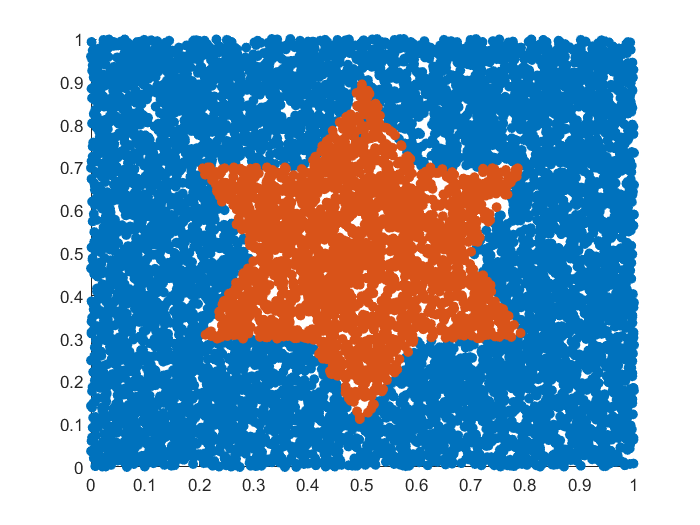

[data_XA, data_YA, data_XB, data_YB] = random_data_generator(10000,200, "Ster");


figure
hold on
axis([0 1 0 1])
%scatter(X,Y,[],'filled')
scatter(data_XB,data_YB,'filled')
scatter(data_XA,data_YA,'filled')

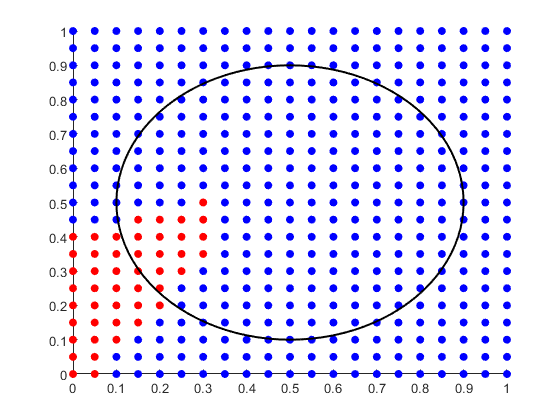

grid = gen_grid();
corClass = correct_classify_circle(grid);
cor_counter = 0;

XA = {};
YA = {};
XB = {};
YB = {};

for c = 1:length(grid)
    x = [grid(1,c); grid(2,c)];
    probs = classify(x,network);
    if probs(1) >= probs(2)
        XA = [XA, grid(1,c)];
        YA = [YA, grid(2,c)];
    else
        XB = [XB, grid(1,c)];
        YB = [YB, grid(2,c)];
    end
end

XA = cell2mat(XA);
YA = cell2mat(YA);
XB = cell2mat(XB);
YB = cell2mat(YB);

th = 0:pi/50:2*pi;
xunit = 0.4 * cos(th) + 0.5;
yunit = 0.4 * sin(th) + 0.5;


    
figure
hold on
axis([0 1 0 1])
scatter(XA,YA,'blue','filled')
scatter(XB,YB,'red','filled')
plot(xunit,yunit,'black','LineWidth',1.5);
hold off

grid = gen_grid()

